#### 4. Given a signal 𝑥(𝑡) = 5 sin(2𝜋𝑡) + 2 sin(10𝜋𝑡).

#### a. Plot 𝑥(𝑡) for t=nT, where T=1/50 sec ant n=0, 1, ………150.

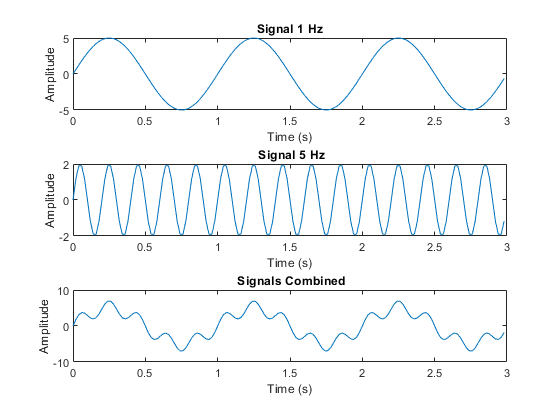

n = 0:1:150-1;
T =  1/50;
t = n*T;

x1 =  5 * sin(2*pi*t);
x2 =  2 * sin(2*5*pi*t);
x =  x1+x2;

figure;
subplot(3,1,1)
plot(t,x1)
title("Signal 1 Hz")
ylabel("Amplitude")
xlabel("Time (s)")

subplot(3,1,2)
plot(t,x2)
title(" Signal 5 Hz")
ylabel("Amplitude")
xlabel("Time (s)")

subplot(3,1,3)
plot(t,x)
title(" Signals Combined")
ylabel("Amplitude")
xlabel("Time (s)")

#### b. Design a digital filter that will pass the 1-HZ signal with attenuation less than 1 dB and suppress the 5-HZ signal to at least 50 dB down from the magnitude of the 1-HZ signal.

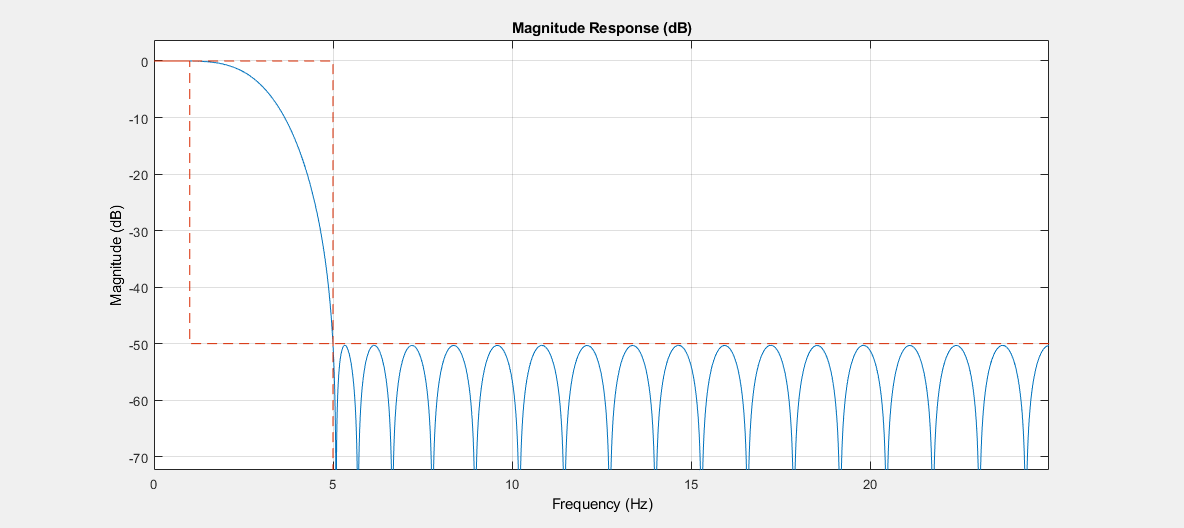

fs = 1/T; % Sampling Frequency

wp = 1/(fs/2); % digital Passband Normalized freq 
ws = 5/(fs/2); % digital Stopband Normalized freq 
Ap = 0.01; % Passband ripple in dB
As = 50; % Stopband attenuation in dB

% Filter Design
lpFilt = designfilt('lowpassfir','PassbandFrequency',wp, ...
         'StopbandFrequency',ws,'PassbandRipple',Ap, ...
         'StopbandAttenuation',As);

figure;
fvtool(lpFilt)

#### c. Find the H(z) of part (b).

[b,a] = tf(lpFilt)

b =     0.0025    0.0022    0.0023    0.0014   -0.0006   -0.0038   -0.0078   -0.0118   -0.0146   -0.0149   -0.0113   -0.0030    0.0105    0.0286    0.0502    0.0732    0.0949    0.1128    0.1246    0.1287    0.1246    0.1128    0.0949    0.0732    0.0502    0.0286    0.0105   -0.0030   -0.0113   -0.0149   -0.0146   -0.0118   -0.0078   -0.0038   -0.0006    0.0014    0.0023    0.0022    0.0025


a = 1

**BONUS**

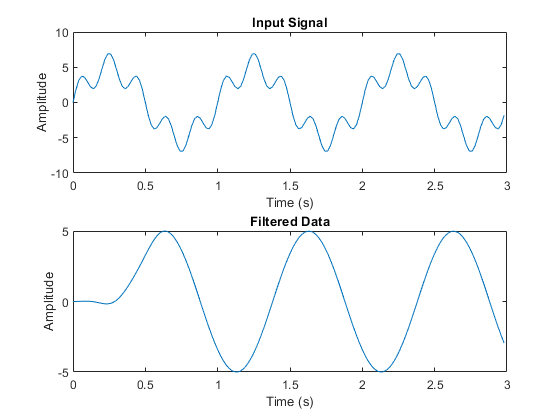

subplot(2,1,1)
plot(t,x)
title("Input Signal")
ylabel("Amplitude")
xlabel("Time (s)")

filteredData = filter(lpFilt,x); % Filter Data 
subplot(2,1,2)
plot(t,filteredData)
title("Filtered Data")
ylabel("Amplitude")
xlabel("Time (s)")

**Power Spectrum**

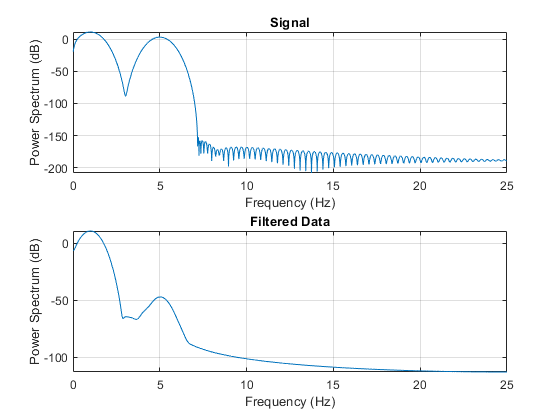

figure;
subplot(2,1,1)
pspectrum(x,fs)
title("Signal")

subplot(2,1,2)
pspectrum(filteredData,fs)
title("Filtered Data")